# 3.1 四种傅里叶表示：教师课堂演示

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。 仅使用基础 MATLAB。图和本次核验数据写入同目录 results。 新编教学案例；连续变换按解析表达式取点显示，不以 FFT 冒充 CTFT。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');   % 由 build_mlx 设置：Live Script 里每格单独一张图，便于阅读；普通运行时拼成一张图存 PNG
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end   % 图例：Live 模式放图下方不压数据；拼图模式自动避让
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：同一类脉冲的四种表示

每次只改一个参数：T=8改16，或N=8改16，然后重新运行。

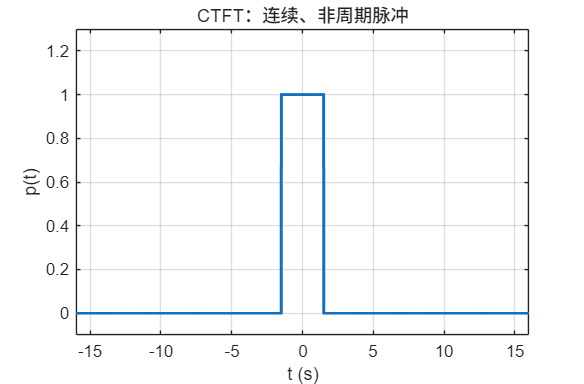

width = 3; T = 8; N = 8;
assert(T > width && N >= 4 && N == fix(N));
t = linspace(-16,16,6401);
Omega = linspace(-4*pi,4*pi,3201);
w = linspace(-4*pi,4*pi,3201);
n = -16:16;
m = -floor(4*pi/(2*pi/T)):floor(4*pi/(2*pi/T));
k = -2*N:2*N;
omega0 = 2*pi/T;
p = double(abs(t) < width/2);
periodicP = double(abs(mod(t+T/2,T)-T/2) < width/2);
P = width*sinc_unscaled(Omega*width/2);
c = (width/T)*sinc_unscaled(m*omega0*width/2);
x = double(abs(n) <= 1);
periodicX = double(ismember(mod(n,N),[0,1,N-1]));
X = 1+2*cos(w);
% 本教材DFS约定：正变换不除N，逆变换除N。
Xdfs = 1+2*cos(2*pi*k/N);

if ~LIVE, f1 = figure('Name','01 四种傅里叶表示','Color','w','Position',[60 40 1250 1000]); end
if ~LIVE, tiledlayout(4,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); plot(t,p,'LineWidth',1.8); ylim([-0.1 1.3]); xlim([-16 16]);
title('CTFT：连续、非周期脉冲'); xlabel('t (s)'); ylabel('p(t)'); grid on;

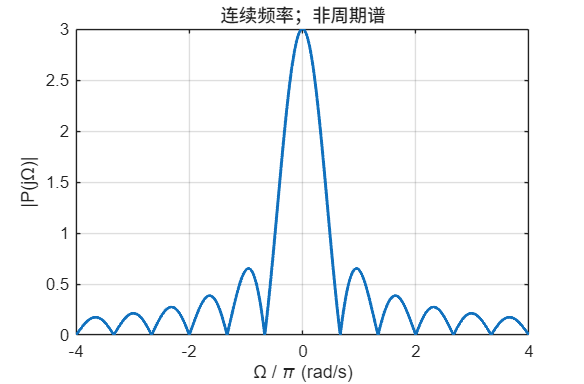

newpanel(); plot(Omega/pi,abs(P),'LineWidth',1.8); grid on;
title('连续频率；非周期谱'); xlabel('\Omega / \pi (rad/s)'); ylabel('|P(j\Omega)|');

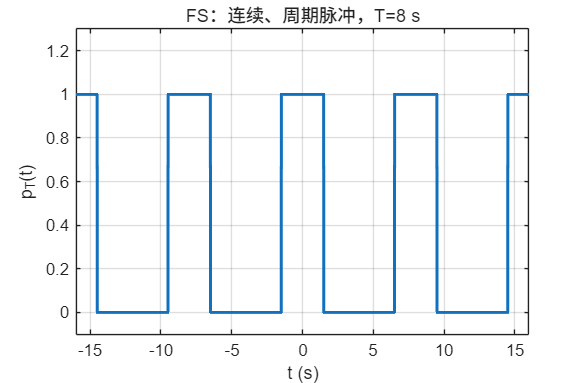

newpanel(); plot(t,periodicP,'LineWidth',1.8); ylim([-0.1 1.3]); xlim([-16 16]);
title(sprintf('FS：连续、周期脉冲，T=%g s',T)); xlabel('t (s)'); ylabel('p_T(t)'); grid on;

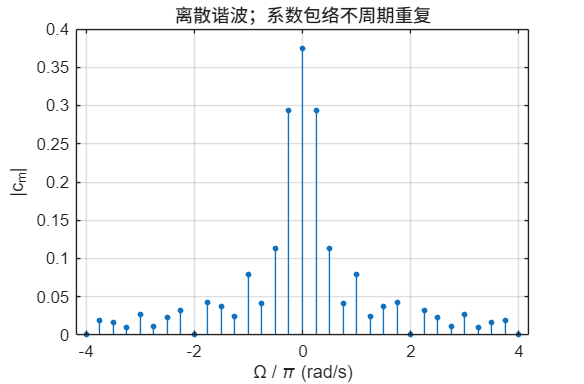

newpanel(); stem(m*omega0/pi,abs(c),'filled','MarkerSize',3); grid on;
title('离散谐波；系数包络不周期重复'); xlabel('\Omega / \pi (rad/s)'); ylabel('|c_m|');

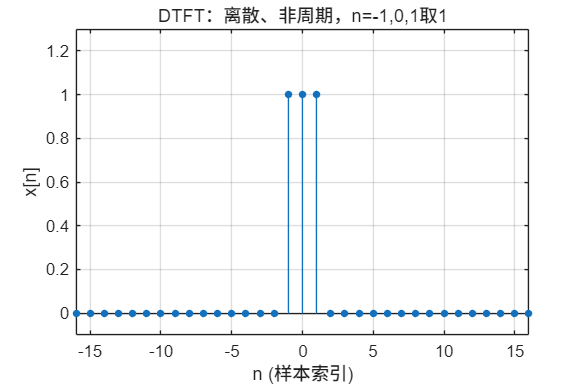

newpanel(); stem(n,x,'filled','MarkerSize',4); ylim([-0.1 1.3]); xlim([-16 16]);
title('DTFT：离散、非周期，n=-1,0,1取1'); xlabel('n (样本索引)'); ylabel('x[n]'); grid on;

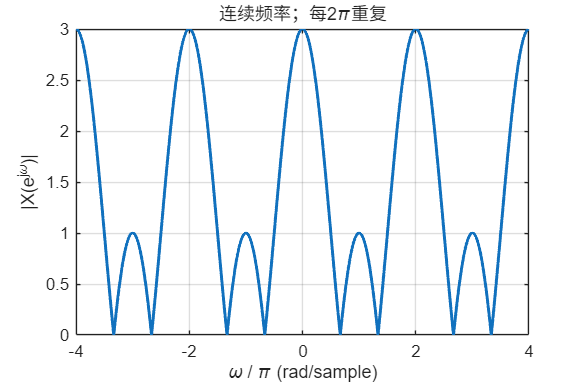

newpanel(); plot(w/pi,abs(X),'LineWidth',1.8); grid on;
title('连续频率；每2\pi重复'); xlabel('\omega / \pi (rad/sample)'); ylabel('|X(e^{j\omega})|');

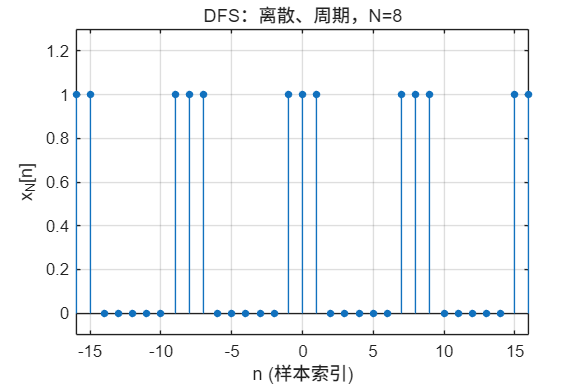

newpanel(); stem(n,periodicX,'filled','MarkerSize',4); ylim([-0.1 1.3]); xlim([-16 16]);
title(sprintf('DFS：离散、周期，N=%d',N)); xlabel('n (样本索引)'); ylabel('x_N[n]'); grid on;

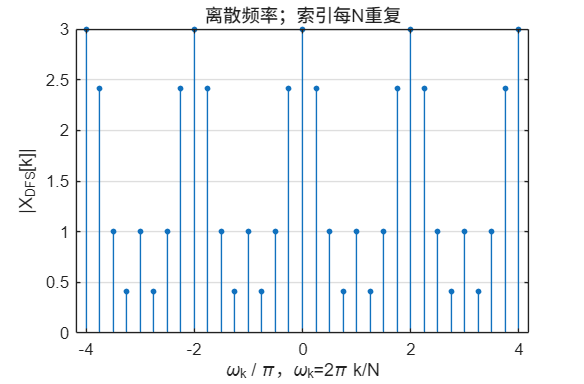

newpanel(); stem(2*k/N,abs(Xdfs),'filled','MarkerSize',3); grid on;
title('离散频率；索引每N重复'); xlabel('\omega_k / \pi，\omega_k=2\pi k/N'); ylabel('|X_{DFS}[k]|');

if ~LIVE, sgtitle('先看横轴，再看连续/离散，最后看周期性；四行幅值归一化不同'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1,fullfile(outdir,'01-four-forms.png'),'Resolution',150); end

## 演示2：周期变长，谱线变密；比较前统一尺度

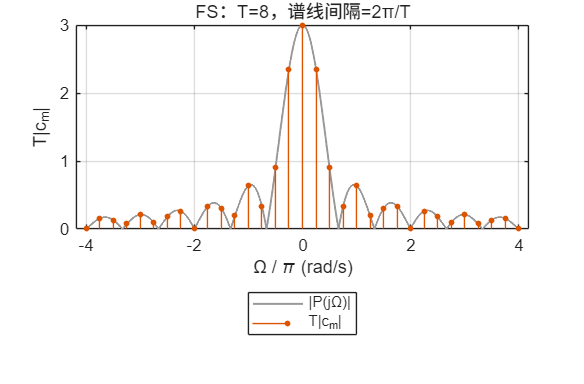

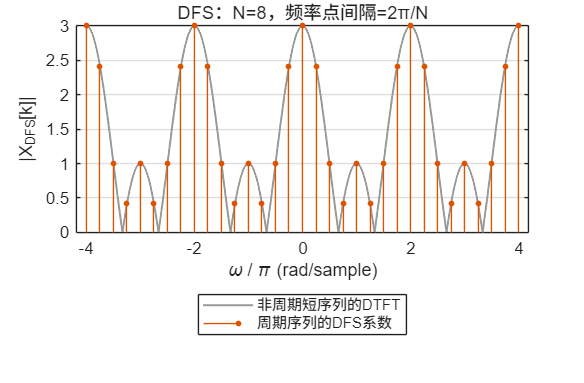

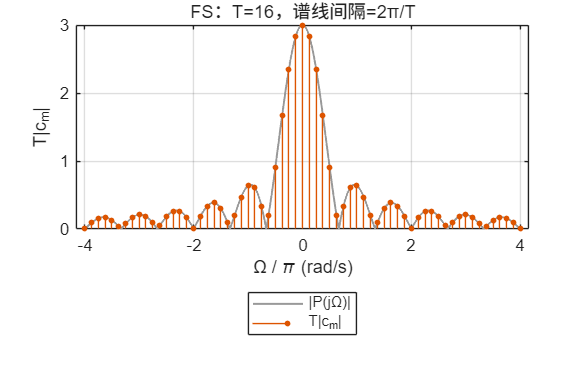

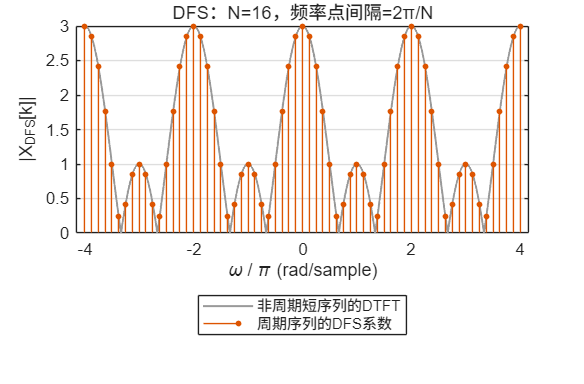

if ~LIVE, f2 = figure('Name','02 周期与谱线间隔','Color','w','Position',[100 80 1250 780]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
for j=1:2
    tj = [8,16]; tj = tj(j);
    mj = -floor(4*pi/(2*pi/tj)):floor(4*pi/(2*pi/tj));
    Omj = 2*pi*mj/tj;
    cj = (width/tj)*sinc_unscaled(Omj*width/2);
    newpanel(j); plot(Omega/pi,abs(P),'Color',[0.6 0.6 0.6],'LineWidth',1.2); hold on;
    stem(Omj/pi,tj*abs(cj),'filled','MarkerSize',3); grid on;
    title(sprintf('FS：T=%d，谱线间隔=2π/T',tj));
    xlabel('\Omega / \pi (rad/s)'); ylabel('T|c_m|');
    legend('|P(j\Omega)|','T|c_m|');
    nj = [8,16]; nj = nj(j); kj=-2*nj:2*nj;
    newpanel(j+2); plot(w/pi,abs(X),'Color',[0.6 0.6 0.6],'LineWidth',1.2); hold on;
    stem(2*kj/nj,abs(1+2*cos(2*pi*kj/nj)),'filled','MarkerSize',3); grid on;
    title(sprintf('DFS：N=%d，频率点间隔=2π/N',nj));
    xlabel('\omega / \pi (rad/sample)'); ylabel('|X_{DFS}[k]|');
    legend('非周期短序列的DTFT','周期序列的DFS系数');
end

if ~LIVE, sgtitle('改周期，观察频率间隔；灰线是不同对象的参照包络'); end
if ~LIVE, prepare_export(f2); end
if ~LIVE, exportgraphics(f2,fullfile(outdir,'02-period-spacing.png'),'Resolution',150); end

## 演示3：有限谐波合成方波，观察跳变附近的过冲

历史讨论采用过其他波形；这里的方波是课堂重构案例。

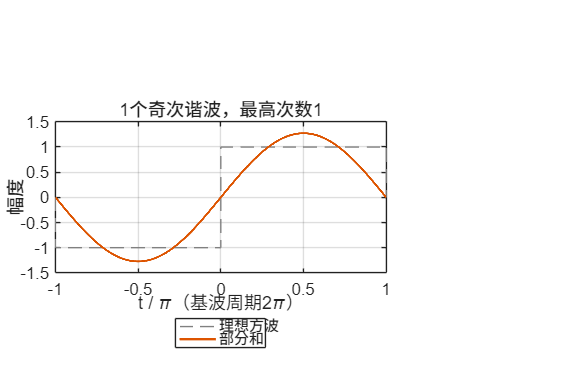

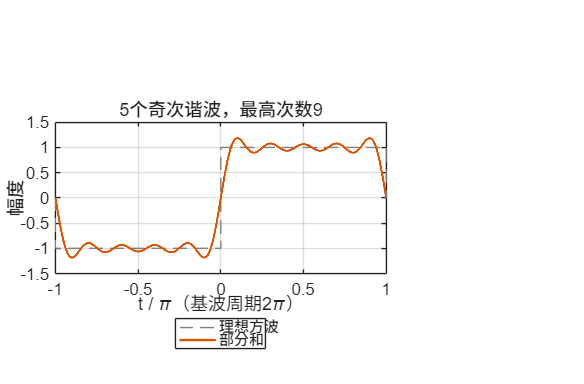

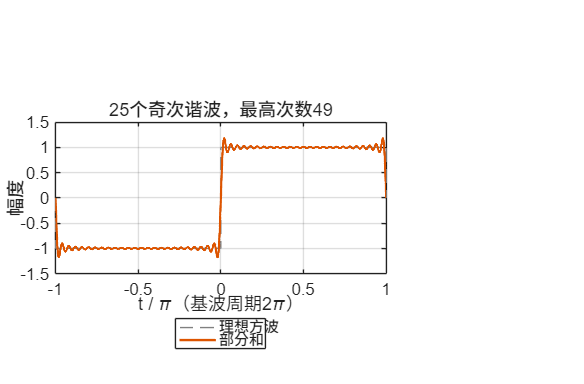

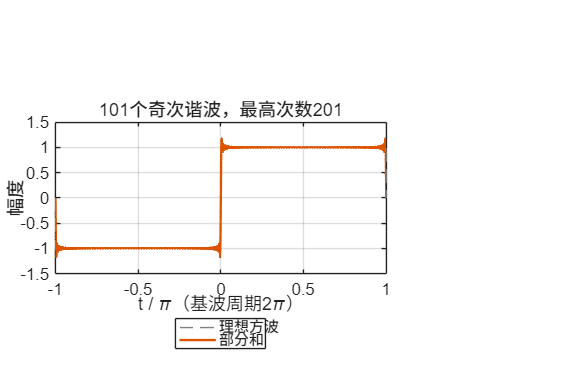

q = linspace(-pi,pi,20001);
truth = sign(sin(q)); truth(abs(sin(q))<1e-12)=0;
counts = [1,5,25,101]; ratios=zeros(size(counts)); errors=zeros(size(counts));
if ~LIVE, f3 = figure('Name','03 方波与Gibbs现象','Color','w','Position',[140 100 1250 780]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
for j=1:numel(counts)
    h = 1:2:(2*counts(j)-1);
    approx = (4/pi)*sum(sin(h(:)*q)./h(:),1);
    newpanel(); plot(q/pi,truth,'--','Color',[0.5 0.5 0.5]); hold on;
    plot(q/pi,approx,'LineWidth',1.4); grid on; ylim([-1.5 1.5]);
    title(sprintf('%d个奇次谐波，最高次数%d',counts(j),h(end)));
    xlabel('t / \pi（基波周期2\pi）'); ylabel('幅度');
    legend('理想方波','部分和');
    % 精确定位本部分和在跳变右侧的第一个峰，避免网格漏峰。
    peakTime = pi/(2*counts(j));
    peakValue = (4/pi)*sum(sin(h*peakTime)./h);
    ratios(j)=(peakValue-1)/2; % 跳变量为2，不能除以平台值1。
    errors(j)=sqrt(mean((approx-truth).^2));
end

if ~LIVE, sgtitle('谐波增多：整体逼近改善，过冲区域变窄；相对跳变量的过冲不趋于零'); end
if ~LIVE, prepare_export(f3); end
if ~LIVE, exportgraphics(f3,fullfile(outdir,'03-gibbs.png'),'Resolution',150); end

## 教师核验：公式、直接求和、数值积分与fft互相对照

testOmega=[0,0.7,2*pi/3,2.5];
numericP=arrayfun(@(om) integral(@(tt) exp(-1i*om*tt),-width/2,width/2),testOmega);
ctftError=max(abs(numericP-width*sinc_unscaled(testOmega*width/2)));
testM=-5:5;
numericC=arrayfun(@(mm) integral(@(tt) exp(-1i*mm*omega0*tt),-width/2,width/2)/T,testM);
fsError=max(abs(numericC-(width/T)*sinc_unscaled(testM*omega0*width/2)));
directDTFT=sum(exp(-1i*(-1:1)'*w),1);
dtftError=max(abs(directDTFT-X));
periodError=max(abs((1+2*cos(w+2*pi))-X));
nn=0:N-1; kk=(0:N-1)';
onePeriod=double(ismember(nn,[0,1,N-1]));
directDFS=exp(-1i*2*pi*kk*nn/N)*onePeriod.';
fftDFS=fft(onePeriod).';
dfsError=max(abs(directDFS-fftDFS));
inverseValues=exp(1i*2*pi*nn'*kk'/N)*directDFS/N;
inverseError=max(abs(inverseValues-onePeriod.'));
gridError=max(abs(directDFS-(1+2*cos(2*pi*kk/N))));
checks=[ctftError,fsError,dtftError,periodError,dfsError,inverseError,gridError];
assert(all(checks<1e-10),'解析式与数值核验不一致');
assert(abs(ratios(end)-0.08949)<1e-4,'Gibbs过冲比例异常');
assert(all(diff(errors)<0),'方波逼近均方根误差未按预期下降');
metrics=struct('matlab_version',version,'run_at',char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')),...
    'pulse_width',width,'T',T,'N',N,'ctft_integral_error',ctftError,...
    'fs_integral_error',fsError,'dtft_sum_error',dtftError,...
    'dtft_periodicity_error',periodError,'dfs_fft_error',dfsError,...
    'dfs_inverse_error',inverseError,'dfs_dtft_grid_error',gridError,...
    'odd_harmonic_counts',counts,'gibbs_overshoot_fraction_of_jump',ratios,...
    'square_wave_grid_rmse',errors,'all_checks_passed',true);
fid=fopen(fullfile(outdir,'verification.json'),'w','n','UTF-8');
assert(fid>=0,'无法创建核验记录');
fprintf(fid,'%s\n',jsonencode(metrics,PrettyPrint=true)); fclose(fid);
disp(metrics);

                      matlab_version: '25.2.0.3360999 (R2025b) Update 7'
                              run_at: '2026-09-18 18:40:25'
                         pulse_width: 3
                                   T: 8
                                   N: 8
                 ctft_integral_error: 1.3682e-16
                   fs_integral_error: 3.5762e-17
                      dtft_sum_error: 2.2204e-16
              dtft_periodicity_error: 4.2188e-15
                       dfs_fft_error: 4.3963e-15
                   dfs_inverse_error: 7.6768e-16
                 dfs_dtft_grid_error: 4.3963e-15
                 odd_harmonic_counts: [1 5 25 101]
    gibbs_overshoot_fraction_of_jump: [0.1366 0.0912 0.0896 0.0895]
               square_wave_grid_rmse: [0.4351 0.2007 0.0895 0.0437]
                   all_checks_passed: 1



fprintf('\n课堂图已保存到：%s\n',outdir);


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function y=sinc_unscaled(z)
% sin(z)/z，避免与MATLAB sinc的pi归一化混淆。
y=ones(size(z)); nonzero=(z~=0); y(nonzero)=sin(z(nonzero))./z(nonzero);
end

function prepare_export(fig)
axesList=findall(fig,'Type','axes');
for a=1:numel(axesList)
    axesList(a).Toolbar.Visible='off';
end
drawnow;
end